P = 1;Q = 11;d = 0.5;
K = 4; M = 2;Rc = 100;

% --- Define Network Parameters ---
inputSize = M*K+2;         % Dimension of the input feature vector [l_n; u; v]
outputSize = 2*P*Q;         % Dimension of the output [Real(g_n), Imag(g_n)]
numResidualBlocks = 4;  % Number of residual blocks (effectively determining hidden depth)
hiddenDim = 50;         % Number of neurons in hidden layers within blocks (tune this)
dropoutProb = 0;      % Dropout probability for regularization (tune this)
l2Reg = 0;           % L2 regularization factor (tune this)

valratio = 0.2;
N_virtual = P*Q;
N_elements = 16;
gpr_models_mag = cell(N_virtual, 1);
gpr_models_phase = cell(N_virtual, 1);

% cn作为输出
dataFolder = 'dataset/linear_CP_dataset/';  % 你的数据目录
fileList = dir(fullfile(dataFolder + "rotate/", '*.mat'));

N_sample = 100;
X_set = [];
Y_set = [];

for i = 1:320
    filename = sprintf( dataFolder + "Gn_%d", i);
    load(filename + ".mat");
    points = model_points{1};
    
    for f = 1
        ln_all = zeros(K*M +2 , N_elements);
        for j = 1:16
            ln_all(:,j) = calculate_ABE_features_1(j, model_points{1}, K, M, Rc, 15, [Inf,Inf], 100, 10);
        end
        X_set = [X_set; ln_all(1:M*K +2,:).'];
    
        sample = 1:2:181;
    
        Gn_theta = G_complex_all(sample, 1, f, :);
        Gn_phi = G_complex_all(sample, 2, f, :);

        Gn = Gn_theta;
        Gn = reshape(Gn, [size(sample, 2) N_elements]);
        Y_set = [Y_set; Gn.'];
    end
end

% for i = 1:length(fileList)
%     load(fullfile(dataFolder + "rotate", fileList(i).name));
% 
%     points = model_points{1};
%     
%     ln_all = zeros(K*M*2 , N_elements);
%     for j = 1:16
%         ln_all(:,j) = calculate_ABE_features(j, model_points{1}, K, M, 40, 15, [Inf,Inf]);
%     end
%     X_set = [X_set; ln_all(1:2*K,:).'];
%     Y_set = [Y_set; G_complex_all.'];
% end

g_ave_complex = mean(Y_set, 1);
theta_ = -90:2:90;phi_start = 0;
u_ = sind(theta_).' * cosd(phi_start);
v_ = sind(theta_).' * sind(phi_start);
angles_uv = [u_(:), v_(:)];

cn_set = [];
train_target_mag = [];
train_target_phase = [];
for i = 1:size(Y_set)
    cn_set(i,:) = calculate_virtual_excitations(Y_set(i,:).', P, Q, d,angles_uv, g_ave_complex.').';
end

cn_set_complex = cn_set;
% cn_set = [abs(cn_set_complex), angle(cn_set_complex)];
cn_set = [real(cn_set_complex), imag(cn_set_complex)];

% 获取训练和测试索引
idxTrain = 1:3000;
idxTest = 3001:3200;

% 提取训练集和测试集
XTrain = X_set(idxTrain, : );
YTrain = cn_set(idxTrain, :);

XValidation = X_set(idxTest, :);
YValidation = cn_set(idxTest, :);

writematrix([XTrain, YTrain], "dataset/train_dataset.csv");
writematrix([XValidation, YValidation], "dataset/test_dataset.csv")

% transfer to multifrequence
theta_ = -90:2:90;phi_start = 0;
u_ = sind(theta_).' * cosd(phi_start);
v_ = sind(theta_).' * sind(phi_start);
angles_uv = [u_(:), v_(:)];

cn_set = [];
basis_cn = [];
train_target_mag = [];
train_target_phase = [];
for basis_f = 3
    Gn_theta = G_complex_all(sample, 1, basis_f, :);
    Gn_phi = G_complex_all(sample, 2, basis_f, :);
%     Gn = 1/sqrt(2) * (Gn_theta + 1j*Gn_phi);
    Gn = Gn_theta;
    Gn = reshape(Gn, [size(sample, 2) N_elements]);
    g_ave_complex_global = mean(Gn, 2);
end

for f = 1:7
    Gn_theta = G_complex_all(sample, 1, f, :);
    Gn_phi = G_complex_all(sample, 2, f, :);
%     Gn = 1/sqrt(2) * (Gn_theta + 1j*Gn_phi);
    Gn = Gn_theta;
    Gn = reshape(Gn, [size(sample, 2) N_elements]);
    g_ave_complex = mean(Gn, 2);
    basis_function(:, f) = g_ave_complex;
    for i = 1:size(Gn, 2)
        cn_set(i, :, f) = calculate_virtual_excitations(Gn(:,i), P, Q, d,angles_uv, g_ave_complex).';
    end
    basis_cn(f, :) = calculate_virtual_excitations(g_ave_complex, P, Q, d, angles_uv, g_ave_complex_global).';
end
cn_set_complex = cn_set;

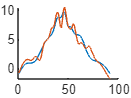

i = 7;f = 7;
predict_aep_complex = reconstruct_aep(cn_set_complex(i, :, 1).', P, Q, d, angles_uv, basis_function(:,f));
figure;hold on;
plot(real(predict_aep_complex));plot(real(G_complex_all(sample, 1, f, i)));

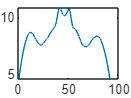

f = 1;
predict_aep_complex = reconstruct_aep(basis_cn(f,:).', P, Q, d, angles_uv, g_ave_complex_global);
figure;plot(real(predict_aep_complex));

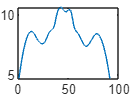

figure;plot(real(basis_function(:,f)));

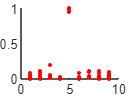

f = 1;
figure; hold on;
for i = 1:P*Q
    scatter(i, real(cn_set_complex(1:16, i, f)), 50, "red", '.');
end
hold off

% validate virtural subarray
load('preds.mat');
YPred = preds;
idxreal = 1:P*Q;idximag = P*Q+1:2*P*Q;
a = YPred(:, idxreal);b = YPred(:, idximag);
pre = a + 1j*b;
% pre = a .* exp(1j*b);
for i = 1:size(pre, 1)
    predict_aep_complex = reconstruct_aep(pre.', P, Q, d, angles_uv, g_ave_complex.');
end
predict_aep_complex = predict_aep_complex.';
predict_aep = [real(predict_aep_complex), imag(predict_aep_complex)];
YValidation_complex = Y_set(idxTest, :);
YValidation_connect = [real(YValidation_complex), imag(YValidation_complex)];
rmse_val = sqrt(mean(sum((YValidation_connect - predict_aep).^2,2)))

rmse_val = single
11.0021

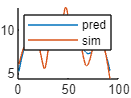

i = 5;
figure;hold on;
plot(real(predict_aep_complex(i,:)));
plot(real(YValidation_complex(i,:)));
legend('pred', 'sim');

% predicted_cn_mag = zeros(N_virtual, size(idxTest, 2));
% predicted_cn_phase = zeros(N_virtual, size(idxTest, 2));
% 
% for i = 1:N_virtual
%     predicted_cn_mag(i, :) = predict(gpr_models_mag{i}, XTest);
%     predicted_cn_phase(i, :) = predict(gpr_models_phase{i}, XTest);
% end
% 
% predicted_cn_complex = predicted_cn_mag .* exp(1j*predicted_cn_phase);
% predicted_cn_complex = predicted_cn_complex.';

% i = 6;
% figure;
% plot(angle(cn_set_complex(idxTest, i)),'b.');
% hold on;
% plot(angle(predicted_cn_complex(:, i)),'r','LineWidth',1.5);
% xlabel('x');
% ylabel('y');
% % legend('Data','GPR predictions');
% hold off

% predicted_gn = zeros(91, size(idxTest, 2));
% for i = 1:size(idxTest, 2)
%     predicted_gn(:,i) = reconstruct_aep(predicted_cn_complex(i, :).', P, Q, d, angles_uv, g_ave_complex.');
% end
% predicted_gn = predicted_gn.';
% gn_complex_target = Y_set(idxTest, :);
% pred_gn_connect = [real(predicted_gn), imag(predicted_gn)];
% 
% gn_complex_connect = [real(gn_complex_target), imag(gn_complex_target)];
% rmse_val = sqrt(mean(sum((pred_gn_connect - gn_complex_connect).^2,2)))
% i = 10;
% figure; hold on;
% plot(real(gn_complex_target(i, :)));
% plot(real(predicted_gn(i, :)));
% hold off;
% 